clear all
d1=load("E:\MTP2\MTP2 final results\Rainy_season_data\LM_bin_results\ppt_sif_bin.mat");
d2=load("E:\MTP2\MTP2 final results\Rainy_season_data\LM_bin_results\ppt_sm_bin.mat");
d3=load("E:\MTP2\MTP2 final results\Rainy_season_data\LM_bin_results\ppt_vod-c_bin.mat");
d4=load("E:\MTP2\MTP2 final results\Rainy_season_data\LM_bin_results\ppt_vod-x_bin.mat");
d5=load("E:\MTP2\MTP2 final results\Rainy_season_data\LM_bin_results\ppt_vod_bin.mat");
d6=load("E:\MTP2\MTP2 final results\Rainy_season_data\LM_bin_results\spi_sif_bin.mat");
d7=load("E:\MTP2\MTP2 final results\Rainy_season_data\LM_bin_results\spi_sm_bin.mat");
d8=load("E:\MTP2\MTP2 final results\Rainy_season_data\LM_bin_results\spi_vod-c_bin.mat");
d9=load("E:\MTP2\MTP2 final results\Rainy_season_data\LM_bin_results\spi_vod-x_bin.mat");
d10=load("E:\MTP2\MTP2 final results\Rainy_season_data\LM_bin_results\spi_vod_bin.mat");




z_r=d6.res(:,:,3);
z_s=d6.res(:,:,1);

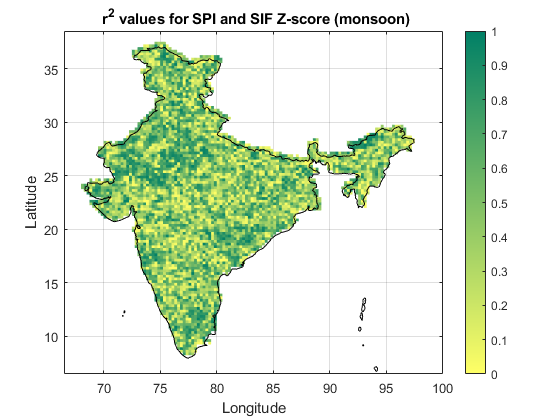

data=z_r;
trial=data(:,:,1);
lat=data(2:130,1,1);
lon=data(1,2:136,1)';
crop1=(data(2:130,2:136,1));
f=figure(1);
%cropf_slope=fliplr(flipud(crop1));
%J(2:130,2:136,1)=fliplr(flipud(crop1));
%slp=pcolor(lon,lat,flipud(cropf_slope));
slp=pcolor(lon,lat,crop1);
slp.EdgeColor='none';
xlabel('Longitude'); % Labelling x axis 
ylabel('Latitude'); % Labelling y axis
title(' r^2 values for SPI and SIF Z-score (monsoon)'); % Putting title to the figure
colormap(flipud(summer)) % Setting a color scheme
hcb1=colorbar; % Showing the scheme on a scale
caxis([0 1])
%title(hcb1,'(in m3/m3)') % Titling a colorbar
grid on % Showing grid lines
hold on % Starting a new plot on same figure retaining the former
geoshow("E:\MTP2\precipitation\shapefile\india.shp",'FaceAlpha',0); % Plotting shapefile of India - you should have a .shp shapefile
saveas(f,"E:\MTP2\MTP2 final results\slope and r2 maps June_Sept\sif\r2 SPI_SIF.jpg");

%  

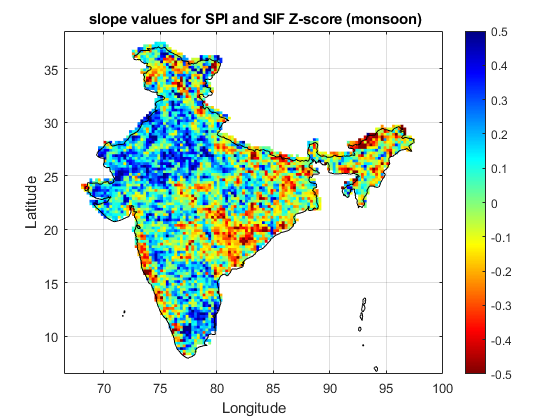

data=z_s;
trial=data(:,:,1);
lat=data(2:130,1,1);
lon=data(1,2:136,1)';
crop1=(data(2:130,2:136,1));
f=figure(2);
%cropf_slope=fliplr(flipud(crop1));
%J(2:130,2:136,1)=fliplr(flipud(crop1));
%slp=pcolor(lon,lat,flipud(cropf_slope));
slp=pcolor(lon,lat,crop1);
slp.EdgeColor='none';
xlabel('Longitude'); % Labelling x axis 
ylabel('Latitude'); % Labelling y axis
title(' slope values for SPI and SIF Z-score (monsoon)'); % Putting title to the figure
colormap(flipud(jet)) % Setting a color scheme
hcb1=colorbar; % Showing the scheme on a scale
caxis([-0.5 0.5])
%title(hcb1,'(in m3/m3)') % Titling a colorbar
grid on % Showing grid lines
hold on % Starting a new plot on same figure retaining the former
geoshow("E:\MTP2\precipitation\shapefile\india.shp",'FaceAlpha',0); % Plotting shapefile of India - you should have a .shp shapefile
saveas(f,"E:\MTP2\MTP2 final results\slope and r2 maps June_Sept\sif\slope SPI_SIF.jpg");

%  